clear
close all
clc

# FIR design-metoder

Der skal stiftes bekendtskab med de almindeligste metoder til design af FIR-filtre. Metoderne gennemføres med MATLABs kommandolinje, men den indbyggede GUI (filterDesigner) kan også anvendes.

## 1. FIR type 1-4 og generaliseret lineær fase

De 4 typer af lineær fase FIR-filtre er karakteriseret ved hhv. lige/ulige filterorden og symmetrisk/antisymmetrisk impulsrespons. Her benævnes filterets orden M. Et M'te ordens FIR-filter er karakteriseret ved M+1 filterkoefficienter.

**Type 1 (lineær fase)**

Filterorden M er lige, impulsrespons er symmetrisk.

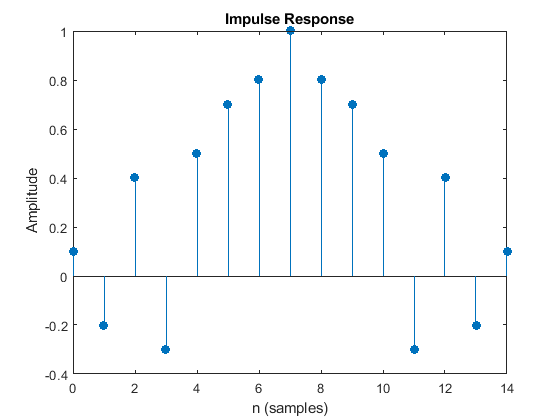

h_del = [0.1 -0.2 0.4 -0.3 0.5 0.7 0.8];
h1 = [h_del 1 fliplr(h_del)];

% Impulsrespons tjekkes
impz(h1,1) % (Symmetrisk)

Da der her er 15 filterkoefficienter, må filteret være af orden 14 (M = 14).

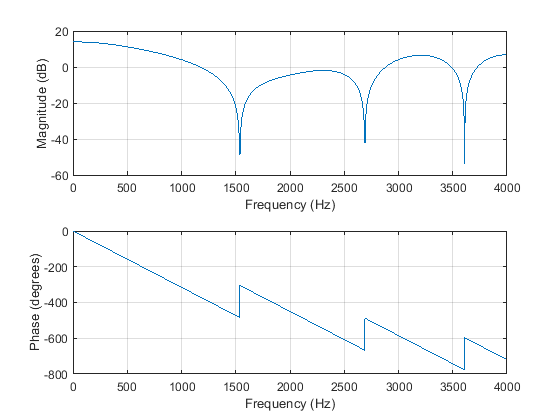

%Der anvendes alle steder her:
fs = 8000;

freqz(h1,1,1024,fs)

Fasen hopper opad hver gang amplituden dykker mod uendeligt (ved poler).

Forsinkelsen tjekkes

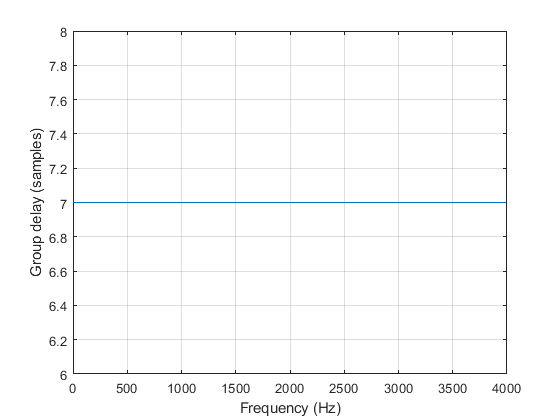

grpdelay(h1,1,1024,fs)

Den er som forventet jvf. fasekarakteristikken.

Nulpunkter indtegnes og sammenlignes med amplitudekarakteristik.

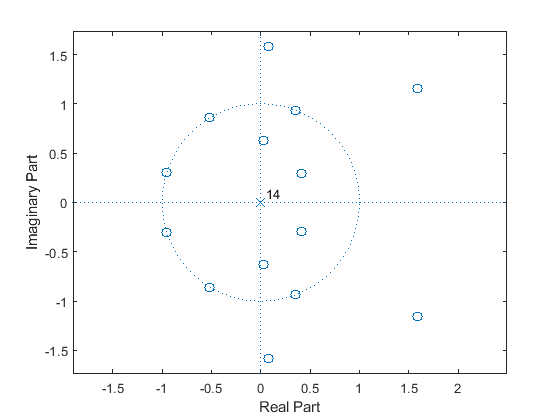

zplane(h1,1)

**Type 2 (lineær fase)**

Filterorden M er ulige, impulsrespons er symmetrisk.

h2 = [h_del 1 1 fliplr(h_del)];

Alle undersøgelser fra Type 1 gentages

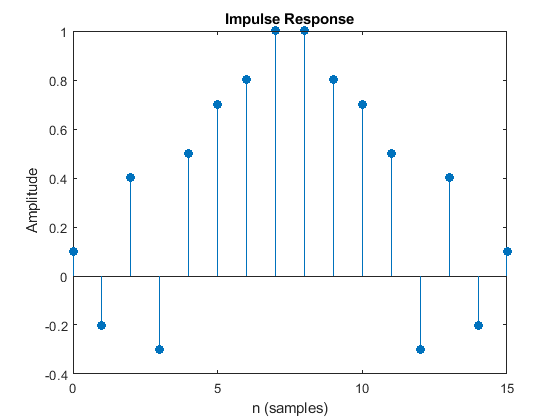

impz(h2,1)

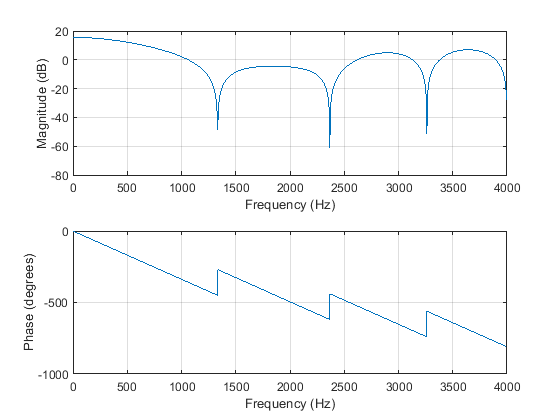

freqz(h2,1,1024,fs)

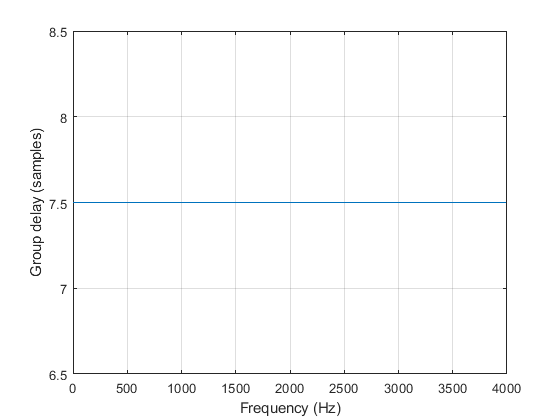

grpdelay(h2,1,1024,fs)

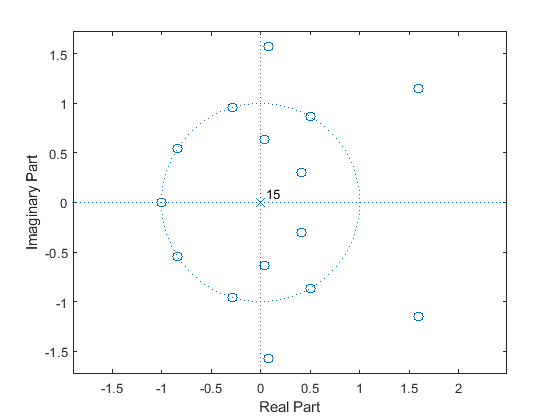

zplane(h2,1)

Ligner næsten på en prik. Filterorden er én højere og amplitudekarakteristikken er derfor marginalt ændret.

**Type 3 (generaliseret lineær fase)**

Filterorden M er lige, impulsrespons er antisymmetrisk.

h3 = [h_del 0 -fliplr(h_del)];

Alle undersøgelser gentages. Der fokuseres på 90 graders fasedrejning.

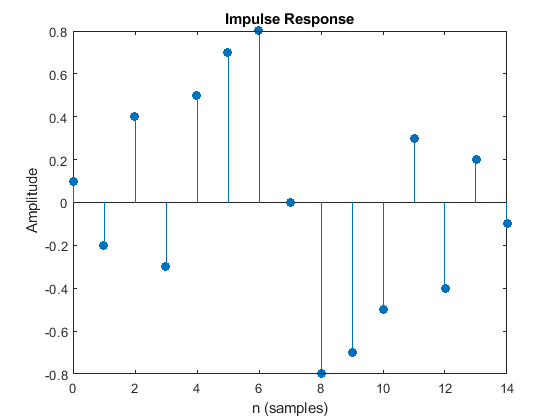

impz(h3,1)

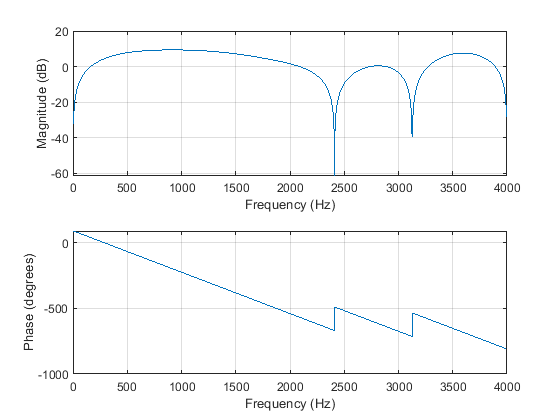

freqz(h3,1,1024,fs)

grpdelay(h3,1,1024,fs)

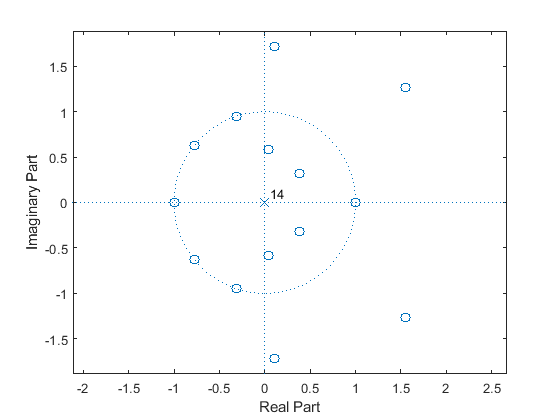

zplane(h3,1)

Impulsrespons er antisymmetrisk som forventet. Fasen starter 90 grader højere. Der er færre poler på enhedscirklen.

**Type 4 (generaliseret lineær fase)**

Filterorden M er ulige, impulsrespons er antisymmetrisk.

h4 = [h_del 0 0 -fliplr(h_del)];

Som med type 3 undersøges.

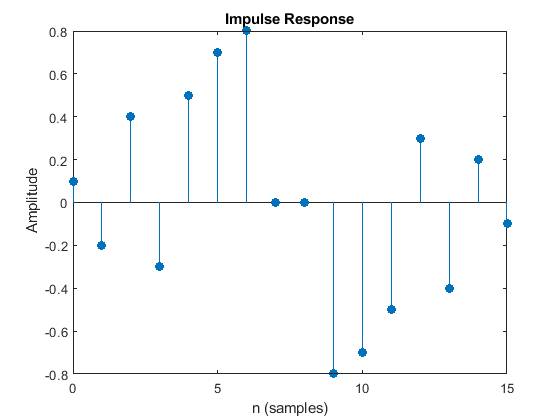

impz(h4,1)

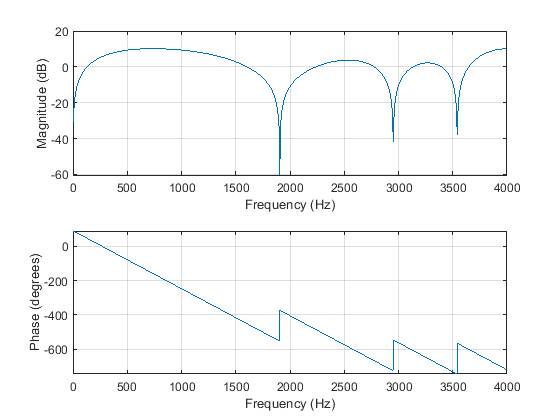

freqz(h4,1,1024,fs)

grpdelay(h4,1,1024,fs)

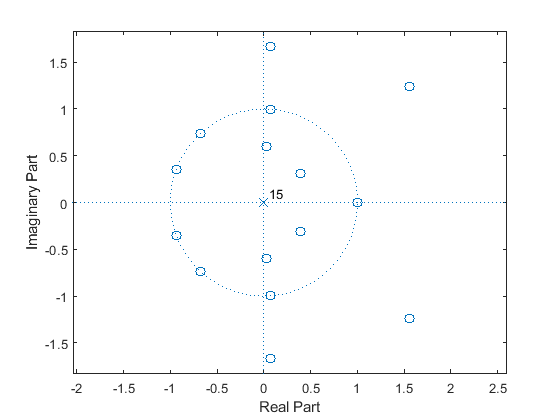

zplane(h4,1)

Fasen starter i 90 grader.

## 2. Filterspecifikation i dB og i absolut skala

Både filterspecifikationer i dB og absolutte værdier anvendes af MATLAB, og man skal derfor kunne skifte mellem dem.

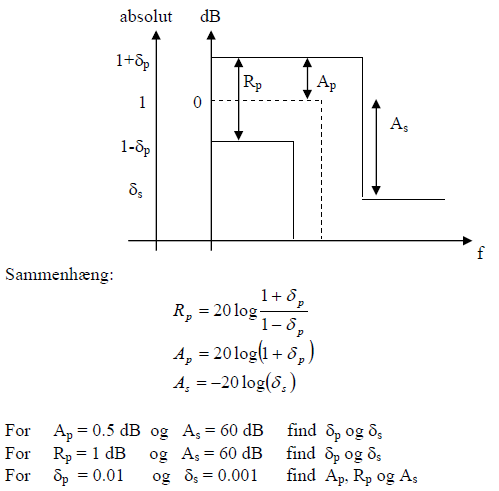

## 3. FIR-design med window-metoden (IDTFT-baseret)

**3a. Princip bag modellen**

Den ønskede idelle amplitudekarakteristik specificeres. Ved invers Fourier-transformation (IDTFT) findes den idelle impulsrespons. Denne trunkeres til ønsket filterlængde M+1 med en vinduesfunktion og gøres kausal (realiserbar i real-time) ved delay på M/2 samples.

**3b. Standardfiltre**

Læs om fir1.

help fir1

 fir1   FIR filter design using the window method.
    B = fir1(N,Wn) designs an N'th order lowpass FIR digital filter
    and returns the filter coefficients in length N+1 vector B.
    The cut-off frequency Wn must be between 0 < Wn < 1.0, with 1.0
    corresponding to half the sample rate.  The filter B is real and
    has linear phase.  The normalized gain of the filter at Wn is
    -6 dB.
 
    B = fir1(N,Wn,'high') designs an N'th order highpass filter.
    You can also use B = fir1(N,Wn,'low') to design a lowpass filter.
 
    If Wn is a two-element vector, Wn = [W1 W2], fir1 returns an
    order N bandpass filter with passband  W1 < W < W2. You can
    also specify B = fir1(N,Wn,'bandpass').  If Wn = [W1 W2],
    B = fir1(N,Wn,'stop') will design a bandstop filter.
 
    If Wn is a multi-element vector,
           Wn = [W1 W2 W3 W4 W5 ... WN],
    fir1<

Denne er den grundlæggende funktion til FIR-design med window-metoden. Herunder anvendes Kaiser:

help kaiser

 kaiser Kaiser window.
    W = kaiser(N) returns an N-point Kaiser window in the column vector W.
  
    W = kaiser(N,BTA) returns the BETA-valued N-point Kaiser window.
        If omitted, BTA is set to 0.500.
 
    % Example:
    %   Create a 200-point Kaiser window with a beta of 2.5 and display 
    %   the result using WVTool.
 
    w = kaiser(200,2.5);
    wvtool(w)
 
    See also chebwin, gausswin, tukeywin, window.

    Reference page for kaiser



help kaiserord

    kaiserord FIR order estimator (lowpass, highpass, bandpass, multiband).
    [N,Wn,BTA,FILTYPE] = kaiserord(F,A,DEV,Fs) is the approximate order N,
    normalized frequency band edges Wn, Kaiser window beta parameter BTA
    and filter type FILTYPE to be used by the FIR1 function:
       B = FIR1(N, Wn, FILTYPE, kaiser( N+1,BTA ), 'noscale' )
 
    The resulting filter will approximately meet the specifications given
    by the input parameters F, A, and DEV.
 
    F is a vector of band edge frequencies in Hz, in ascending order
    between 0 and half the sampling frequency Fs.  A is a vector of 0s and
    1s specifying the desired function's amplitude on the bands defined by
    F. The length of F is twice the length of A, minus 2 (it must therefore
    be even).  The first frequency band is assumed to start at zero, and
    the last one always ends at Fs/2.
 
    DEV is a vector of maximum deviations or ripples (in linear units)
    allowable for 

Der ønskes et lavpasfilter med ideel afskæringsfrekvens på 1000 Hz, overgang fra 900 til 1100 Hz, delta_p på 0.01 og delta_s på 0.001.

[M Wn beta type] = kaiserord([900 1100],[1 0],[0.01 0.001],fs)

M = 146

Wn = 0.2500

beta = 5.6533

type = 'low'

Filterkoefficienter udregnes vha. funktionen fir1.

b = fir1(M, Wn, type, kaiser(M+1,beta), 'noscale');

Filterordenen er M = 146.

Kontroller filteret som før:

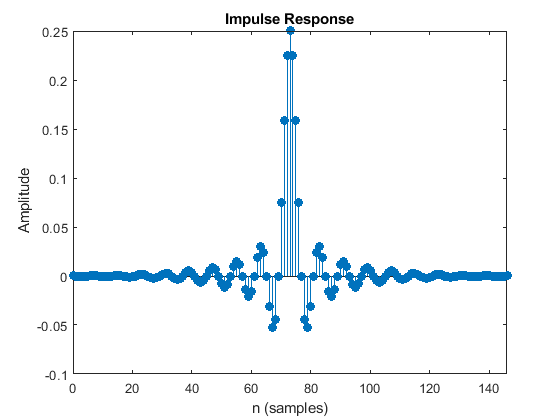

impz(b,1)

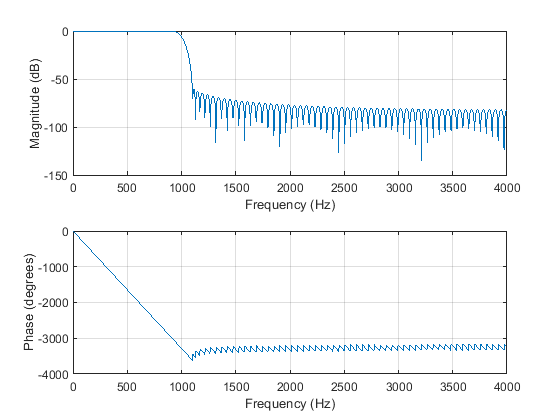

freqz(b,1,1024,fs)

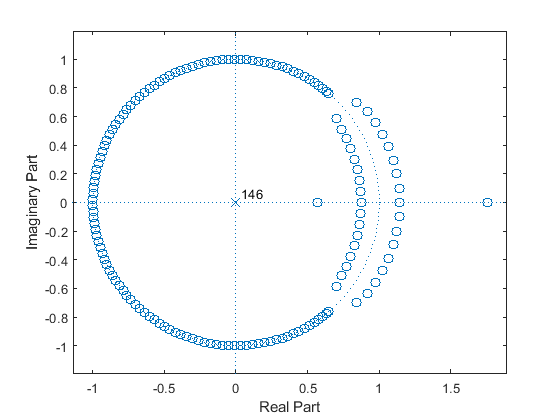

zplane(b,1)

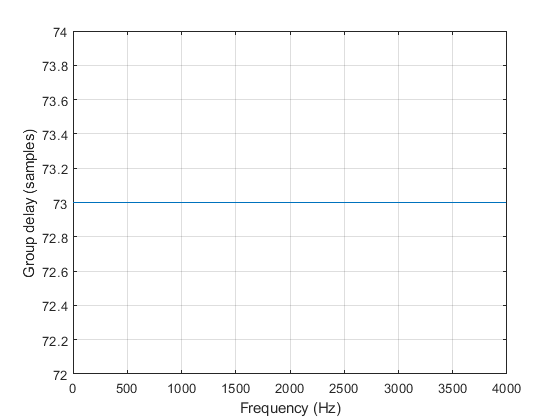

grpdelay(b,1,1024,fs)

Studér ripplens størrelse og forløb nærmere:

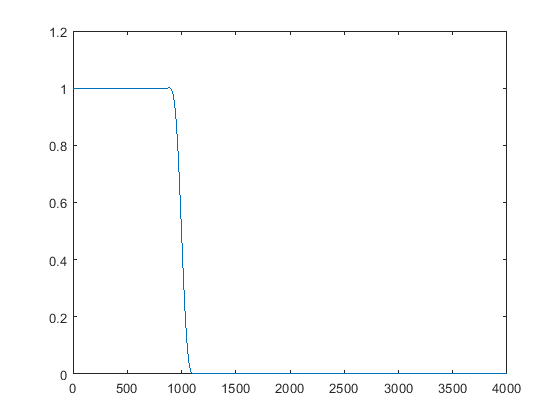

[H f] = freqz(b,1,1024,fs);
plot(f,abs(H))

Rippleværdien ændrer sig over hele båndområderne. Den absolutte værdi af ripplen er af samme størrelse både i pas- og stopbånd.

Et højpasfilter med samme værdier analyseres lignende:

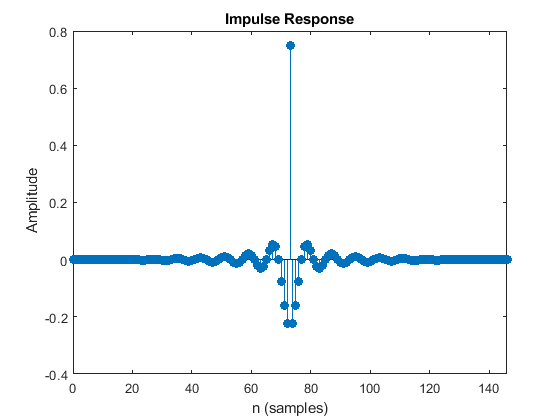

b = fir1(M, Wn, 'high', kaiser(M+1,beta),'noscale');
impz(b,1)

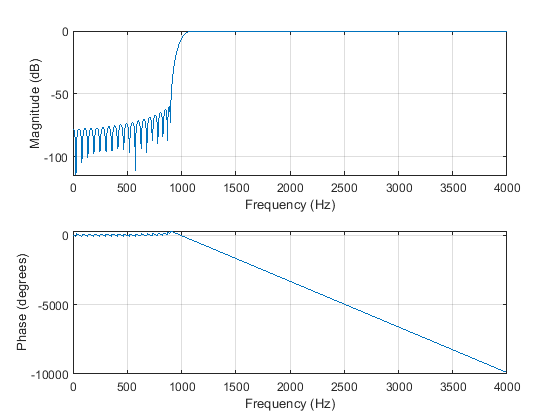

freqz(b,1,1024,fs)

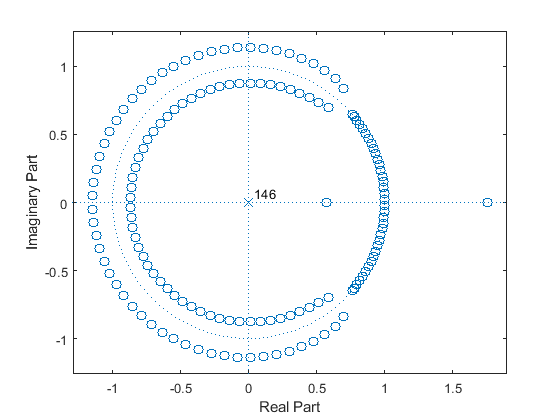

zplane(b,1)

grpdelay(b,1,1024,fs)

Hvis der forsøges at øge ordenen med én, er ordenen ulige. Symmetriske FIR-filtre skal have en gain på 0 ved Nyquist-frekvensen, hvis de skal have en ulige orden. Det er derfor ikke muligt at lave et filter, hvor M er ulige.

**3d. Vilkårlig stykvis lineær amplitudekarakteristik**

Med kommandoen fir2 kan med window-metoden beregnes filtre med en vilkårlig stykvis lineær amplitudekarakteristik.

help fir2

 fir2   FIR arbitrary shape filter design using the frequency sampling method.
    B = fir2(N,F,A) designs an Nth order linear phase FIR digital filter
    with the frequency response specified by vectors F and A and returns
    the filter coefficients in length N+1 vector B.  
 
    The vectors F and A specify the frequency and magnitude breakpoints for
    the desired frequency response. The frequencies in F must be given in
    increasing order with 0.0 < F < 1.0 and 1.0 corresponding to half the
    sample rate. The first and last elements of F must equal 0 and 1
    respectively.
 
    B = fir2(N,F,A,NPT) specifies the number of points, NPT, for the grid
    onto which fir2 linearly interpolates the frequency response. NPT must
    be greater than 1/2 the filter order (NPT > N/2). If desired, you can
    interpolate F and A before passing them to fir2.
 
    B = fir2(N,F,A,NPT,LAP

Der laves et multiband-filter med pasbånd fra 200 til 400 Hz med gain på 0.1, samt et pasbånd fra 1200 til 1600 Hz med gain på 1. delta_p = 0.01 og delta_s = 0.001.

fo = fs/2;
F = [0 200 200 400 400 1200 1200 1600 1600 fo]/fo;
A = [0 0 0.1 0.1 0 0 1 1 0 0];
M = 100; % Startgæt på filterorden
b = fir2(M,F,A);

Filter analyseres og ampltiudekarakteristik plottes sammen med ønsket karakteristik.

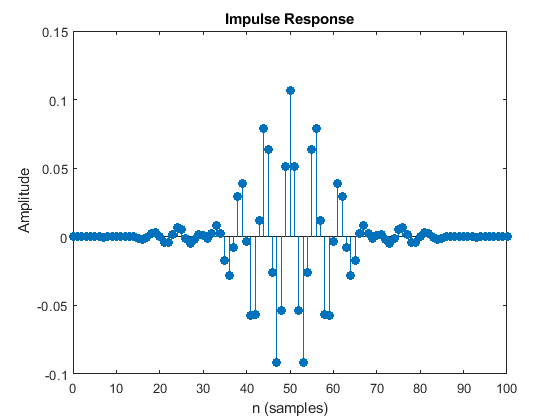

impz(b,1)

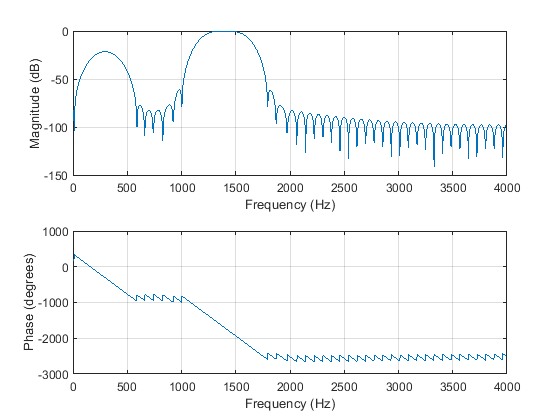

freqz(b,1,1024,fs)

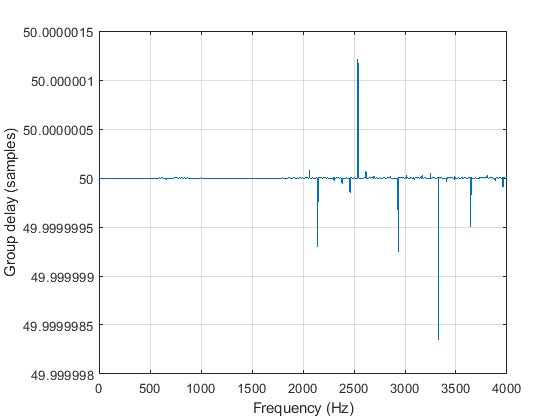

grpdelay(b,1,1024,fs)

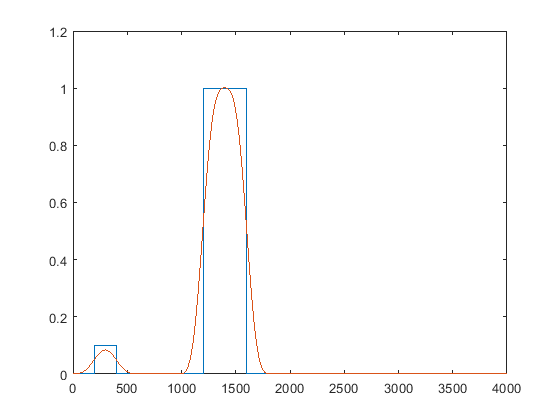


[H f] = freqz(b,1,1024,fs);
plot(F*fo, A, f, abs(H))

## 4. FIR-design med Equiripple Optimal-metoden (REMEZ-baseret)

**4a. Princip bag metoden**

Den ønskede amplitudekarakteristik approksimeres, så der for en given orden findes det filter, hvis maksimale fejl i pasbånd og stopbånd er mindst. Dette filter har en equiripple, altså i modsætning til for window-metoden, vil ripplen være konstant i pasbånd og konstant i stopbånd. Ripplestørrelserne kan ændres individuelt, så de har forskellige størrelser, igen modsat for window-metoden.

Der anvendes her remez- og remezord-funktionerne (FORÆLDET! ny udgave: firpm og firpmord). De er MATLABs grundlæggende funktioner til FIR-design med equiripple-metoden.

help firpm

 firpm Parks-McClellan optimal equiripple FIR filter design.
    B=firpm(N,F,A) returns a length N+1 linear phase (real, symmetric
    coefficients) FIR filter which has the best approximation to the
    desired frequency response described by F and A in the minimax sense. 
    F is a vector of frequency band edges in pairs, in ascending order
    between 0 and 1. 1 corresponds to the Nyquist frequency or half the
    sampling frequency. At least one frequency band must have a non-zero
    width. A is a real vector the same size as F which specifies the
    desired amplitude of the frequency response of the resultant filter B.
 
    The desired response is the line connecting the points (F(k),A(k)) and
    (F(k+1),A(k+1)) for odd k; firpm treats the bands between F(k+1) and
    F(k+2) for odd k as "transition bands" or "don't care" regions. Thus
    the desired amplitude is piecewise linear with transition bands. The
    maximum error 

help firpmord

 firpmord  Parks-McClellan optimal equiripple FIR order estimator.
    [N,Fo,Ao,W] = firpmord(F,A,DEV,Fs) finds the approximate order N, 
    normalized frequency band edges Fo, frequency band magnitudes Ao and 
    weights W to be used by the FIRPM function as follows:
        B = FIRPM(N,Fo,Ao,W)
    The resulting filter will approximately meet the specifications given
    by the input parameters F, A, and DEV.  F is a vector of cutoff
    frequencies in Hz, in ascending order between 0 and half the sampling
    frequency Fs. If you do not specify Fs, it defaults to 2.  A is a
    vector specifying the desired function's amplitude on the bands defined
    by F. The length of F is twice the length of A, minus 2 (it must
    therefore be even).  The first frequency band always starts at zero,
    and the last always ends at Fs/2.  It is not necessary to add these
    elements to the  F vector.  DEV is a vector of maximum deviations or
    ripples (in l

**4b. Standardfiltre**

Der ønskes et lavpasfilter med samme krav som i punkt 3b.

Den approksimerede filterorden kan udregnes med formel fra bogen, eller firpmord:

[M Fo Ao W] = firpmord([900 1100], [1 0], [0.01 0.001], fs)

M = 102

Fo =          0
    0.2250
    0.2750
    1.0000


Ao =      1
     1
     0
     0


W =      1
    10


b = firpm(M, Fo, Ao, W)

b =     0.0004   -0.0006   -0.0013   -0.0021   -0.0023   -0.0017   -0.0004    0.0011    0.0021    0.0019    0.0005   -0.0014   -0.0029   -0.0028   -0.0010    0.0018    0.0039    0.0040    0.0016   -0.0021   -0.0051   -0.0055   -0.0026    0.0024    0.0067    0.0076    0.0039   -0.0027   -0.0087   -0.0103   -0.0058    0.0030    0.0114    0.0142    0.0086   -0.0032   -0.0152   -0.0199   -0.0131    0.0034    0.0213    0.0298    0.0212   -0.0036   -0.0336   -0.0518   -0.0417    0.0036    0.0772    0.1587


Filterordenen er ifølge funktionen M = 102.

Den vanlige analyse udføres

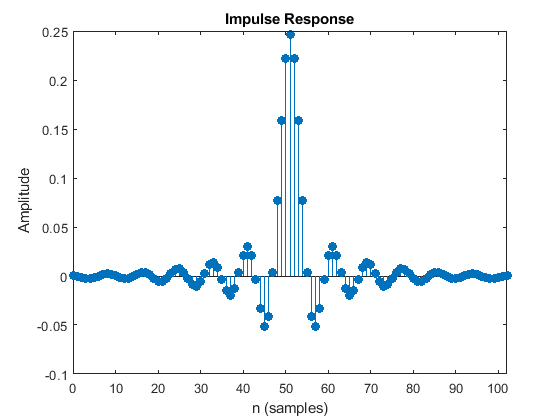

impz(b,1)

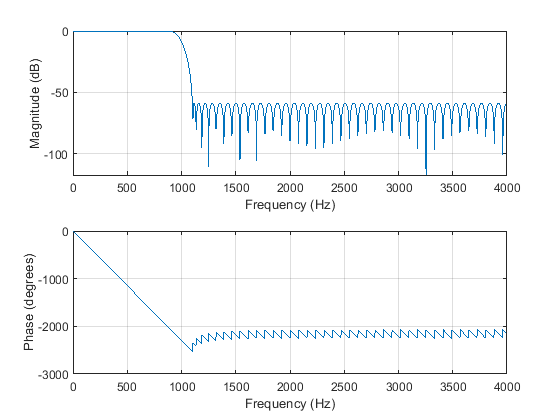

freqz(b,1,1024,fs)

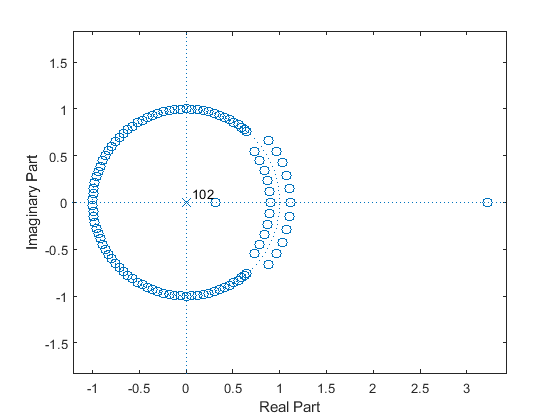

zplane(b,1)

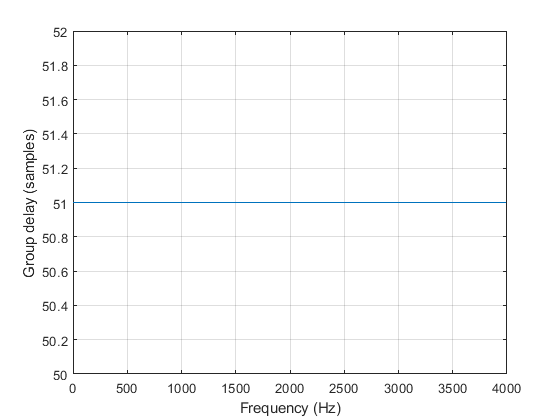

grpdelay(b,1,1024,fs)

Ripplen er her samme størrelse hele vejen gennem pas-/stopbånd. Antallet af ripple-ekstreme skal passe med det teoretiske antal, M/2 +2 (eller M/2 + 3 sjældent).

Filterets orden er over 40 lavere end med window-metoden.

**4c. Vilkårlig stykvis lineær amplitudekarakteristik**

Et lignende eksempel med et multiband-filter fra afsnit 3d udføres.

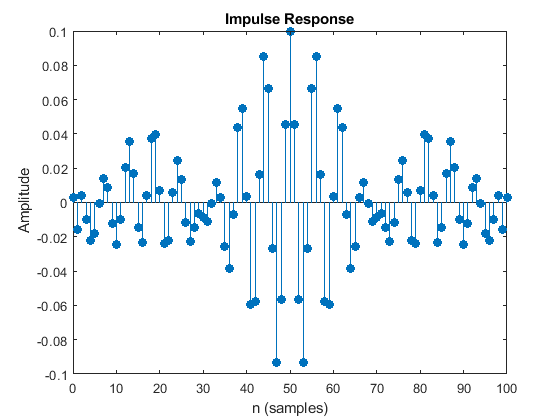

F = [0 180 220 380 420 1180 1220 1580 1620 fo]/fo;
A = [0 0 0.1 0.1 0 0 1 1 0 0];
M = 100; % Startgæt
W = [10 1 10 1 10];
b = firpm(M, F, A, W);

impz(b,1)

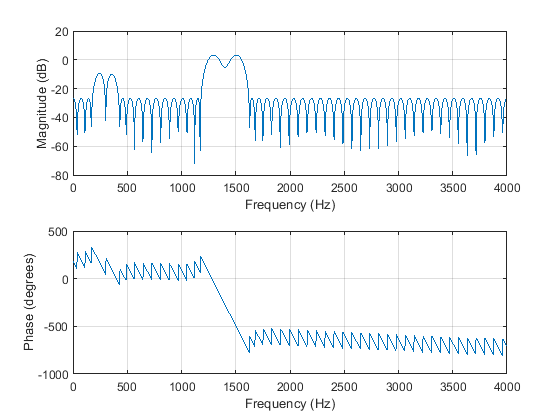

freqz(b,1,1024,fs)

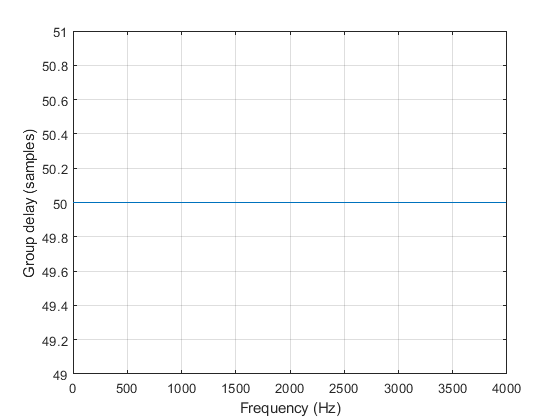

grpdelay(b,1,1024,fs)

## 5. FIR-design med Least Squares-metoden